% initSim
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


L_f = l_f*Lbase1v

L_f = 6.3746e-08

R_f = r_f*Zbase1v

R_f = 4.7610e-06

C_f = 0.0757204*Cbase1v

C_f = 0.3189

% c_f = 0.0757

c_f = 0.0757

% plant
    
G_plant = 1/(s*l_f)

G_plant =
 
     1
  --------
  0.0265 s
 
Continuous-time transfer function.
Model Properties


T_delay = 0.1e-3

T_delay = 1.0000e-04

G_sensor = 1/(1+s*T_delay)

G_sensor =
 
       1
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.
Model Properties


G_i = G_plant*G_sensor

G_i =
 
             1
  -----------------------
  2.65e-06 s^2 + 0.0265 s
 
Continuous-time transfer function.
Model Properties



% f_sw = 10000
f_c = 1/10*f_sw

f_c = 295



Kp_cc = 50

Kp_cc = 50

Ti_cc = 0.003

Ti_cc = 0.0030

% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)  
G_cc = Kp_cc*(1 + s*Ti_cc)/(s*Ti_cc)

G_cc =
 
  0.15 s + 50
  -----------
    0.003 s
 
Continuous-time transfer function.
Model Properties


Kp_cc*(1+1/Ti_cc/s)

ans =
 
  50 s + 1.667e04
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


r_f*f_c

ans = 1.8585

l_f*f_c

ans = 7.8175

Ki_cc = Kp_cc/Ti_cc

Ki_cc = 1.6667e+04


Kp_cc+Ki_cc/s

ans =
 
  50 s + 1.667e04
  ---------------
         s
 
Continuous-time transfer function.
Model Properties



G_openl = G_cc*G_i

G_openl =
 
          0.15 s + 50
  ---------------------------
  7.95e-09 s^3 + 7.95e-05 s^2
 
Continuous-time transfer function.
Model Properties


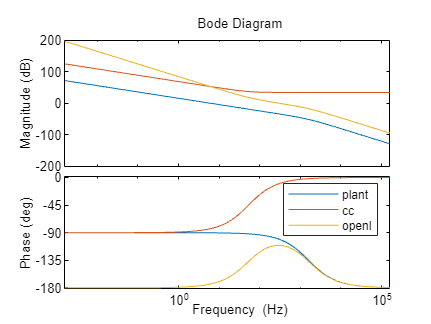



options = bodeoptions;
options.FreqUnits = 'Hz'; % or 'rad/second', 'rpm', etc.
options.PhaseWrapping='on';


bode(G_i,G_cc,G_openl,{10e-3,10e5}, options);
legend('plant', 'cc','openl');

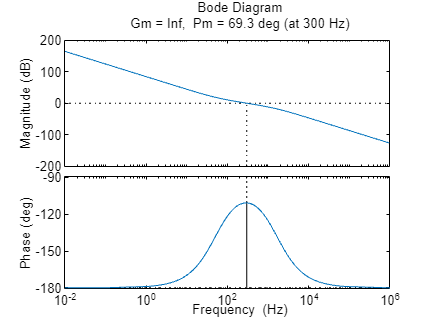

% bode(G_cc/(1+G_cc),{10e-3,10e5})

options.XLim = [10e-3,10e5];
% 
margin(G_openl,options);

% margin(G_cl)
% step(G_cl)
% pzmap(G_cl)

T_ers = 1/(2*pi*f_c)

T_ers = 5.3951e-04

Gapprox = 1/(1+s*T_ers)

Gapprox =
 
         1
  ---------------
  0.0005395 s + 1
 
Continuous-time transfer function.
Model Properties


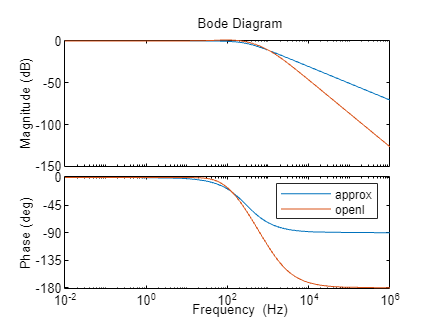

bode(Gapprox,G_openl/(1+G_openl), options);
legend('approx','openl');



P0 = 1

P0 = 1

p_1 = -1/T_ers

p_1 = -1.8535e+03

z_1 = 3*1^2/(2*l_f*P0) % 3*1^2/(2*l_f*P0) %

z_1 = 56.6038

UDC = 2%V_dc

UDC = 2

UNd = 1%Vbase_lv

UNd = 1

C = c_f

C = 0.0757

L = l_f

L = 0.0265

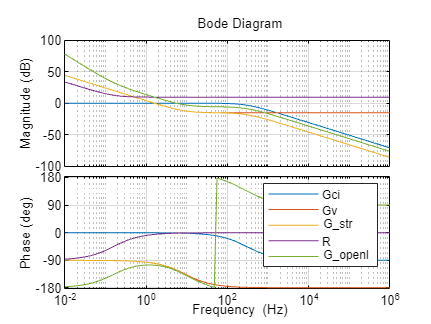


Gu=(3/2*UNd-s*L*P0/UNd)/(s*UDC*C);
Gstr=Gapprox*Gu;


kpu=3;
Tnu=1;
Gcu=kpu*(1+s*Tnu)/(s*Tnu);

n0 = 1/(10^(-5/20));

a = 650;
p = sqrt(a)*2*pi*50;
N = n0*(s+p/a)/(s+p);

Golu=Gcu*Gstr;
Gclu=Golu/(1+Golu); 

figure(3);
bode(Gapprox, Gu, Gstr,Gcu,Golu,options);
legend('Gci', 'Gv', 'G_{str}','R','G_{openl}');
grid on;

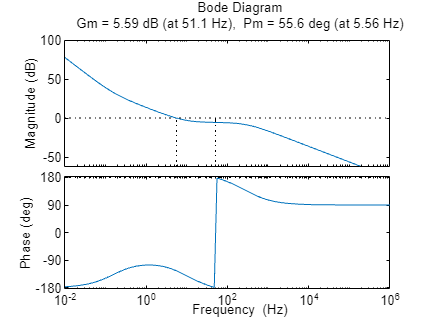

figure(4);
margin(Golu,options)

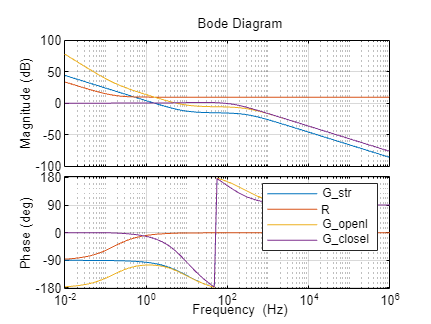

figure(5);
bode(Gstr,Gcu,Golu,Gclu,options);
legend('G_{str}','R','G_{openl}','G_{closel}');
grid on;


% Kp_vc =  40 %C_f/Tau_cc % % 0.05%1/Vbase_lv;C_f*omega_v %
% Ki_vc =  200 % 2*Kp_vc*omega_v^2/omega_c% 2*Kp_vc*Tau_cc%    %1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 


% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
% G_vc = Kp_vc + Ki_vc/s
% 
% G_openl = G_vc*G_cc*G_plant
% G_cl = G_openl/(1+G_openl)

% bode(G_plant,G_cc,G_vc,G_openl,{10e-3,10e5})
% legend('plant', 'cc','vc','openl')
% 
% margin(G_vc)
% bode(G_vc,G_cc,{10e-3,10e5})
% 
% step(G_cl)
% pzmap(G_cl)


% a = 650
% asind((1-a*0.02)/(1+a*0.02))
% sqrt(Ki_vc*1/Tau_cc)
% ans*0.0757204
% G_dc = 0.005*Sbase1*(1+0.005*1/s)
% bode(G_dc,options)

% droop control

% (wmeas-wref)/(Pref-Pmeas) = kp_p

    % kp_p = (0.95-1)/(0.5-1)%0.05
    % 
    % % (vmeas-vref)/(Qref-Qmeas) = -kp_q
    % kp_q = (0.9-1)/(0-0.5)

% (5+0.4/s)/(1-5+0.4/s)
% 
% bode((5+0.4/s)/(1+5+0.4/s))
% 

% c_f=0.07
% H=omega_c/2
% tau_dcc = 2*L_f/3*Sbase1/Vbase_lv^2
% G_dc = -(2/C_f)*(tau_dcc*s+1)/s
% G_cc = 1/(0.005*s+1)
% K_v =C_f/2*H/s
% loop_gain = K_v*G_cc*G_dc
% bode(loop_gain)
% margin(H)
% loop_gain/(1-loop_gain)
% margin(loop_gain/(1-loop_gain))
% 
% 
% 1/0.005*2*pi

## dc

% 
% omega_dc = 2*pi*20
% R_dc = V_dc^2/Sbase1
% Kp_dcc = omega_dc*C_dc
% Ki_dcc = omega_dc       
% 
% 
% options.PhaseWrapping='off';


% ti = 1/f_c
% f_dc = f_c/5
% f_dc*2*pi
% G_i_dc = (0.01*s+1)/(s*0.01)
% (1/0.01)/(1/0.01+s)
% tau_plant = 2/3*L_f*1*Sbase1/Vbase_lv^2
% G_p_dc = -(2/C_f)*(tau_plant*s+1)/s
% G_dc_plant = G_i_dc*G_p_dc
% ks = 225        
% ki = 1
% Gdc = -ks/s
% G_dc_openl = Gdc*G_dc_plant
% n0 = 1/(10^(-23/20))

% a = 200
% p = sqrt(a)*2*pi*f_dc
% N = n0*(s+p/a)/(s+p)

% bode(G_dc_plant,Gdc,G_dc_openl,options)
% legend('plant', 'dc_c','openl')
% bode(N,options)
% margin(N*G_dc_openl,options)
% N*G_dc

%